gtccLength = 18;

## Blackbird vs Nightingale binary SVM classification

class1 = 'TURMER';
class2 = 'LUSMEG';

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

gtccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      30.396 |      0.4732 |      0.4732 |    0.0039801 |       38.319 |
|    2 | Best   |     0.35395 |      23.849 |     0.35395 |      0.3623 |       1.5841 |       188.45 |
|    3 | Best   |     0.16804 |       18.07 |     0.16804 |     0.16807 |       599.95 |       75.147 |
|    4 | Accept |     0.43677 |      34.126 |     0.16804 |     0.16825 |       2.6201 |      0.41813 |
|    5 | Accept |      0.4732 |      29.897 |     0.16804 |     0.16807 |       971.76 |    0.0030739 |
|    6 | Accept |     0.18763 |      20.961 |     0.16804 |     

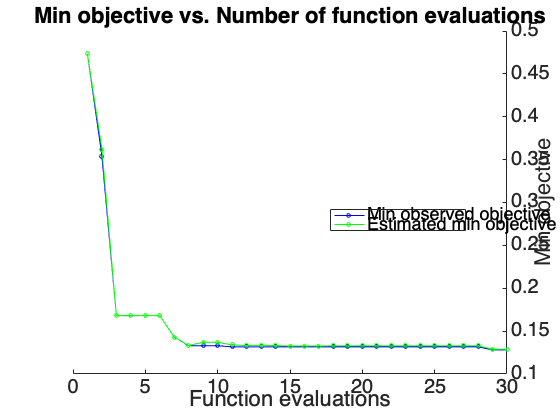

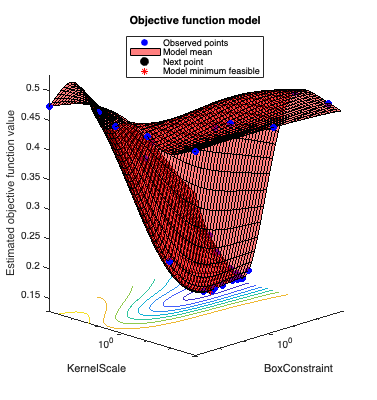


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 863.1009 seconds
Total objective function evaluation time: 827.857

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       52.608          10.452   

Observed objective function value = 0.12818
Estimated objective function value = 0.12891
Function evaluation time = 17.0519

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       52.608          10.452   

Estimated objective function value = 0.12891
Estimated function evaluation time = 23.0735



gtccRbfSvmTURMERxLUSMEG =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1682×1 double]
                                 Bias: -0.0188
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRbfSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,18,'test',50);
[lCA, rbfCA] = testModels(testMatrix1,-1,gtccLinearSvmTURMERxLUSMEG,gtccRbfSvmTURMERxLUSMEG);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 58.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 84.00%


### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,18,'test',50);
[lCA, rbfCA] = testModels(testMatrix2,1,gtccLinearSvmTURMERxLUSMEG,gtccRbfSvmTURMERxLUSMEG);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 94.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 54.00%


## Testing PCA

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

[XTrain95,coeffs95] = projectPCA(XTrain,95);

gtccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.36048 |      3.1285 |     0.36048 |     0.36048 |       19.838 |       915.14 |
|    2 | Accept |     0.42612 |      4.0723 |     0.36048 |     0.36493 |        87.73 |      0.16013 |
|    3 | Best   |     0.28144 |      1.3503 |     0.28144 |     0.28149 |      0.14188 |       4.2911 |
|    4 | Accept |      0.4732 |      1.6781 |     0.28144 |     0.29069 |      0.04198 |    0.0019732 |
|    5 | Accept |      0.2921 |      1.4179 |     0.28144 |     0.28152 |      0.10804 |       3.8044 |
|    6 | Accept |     0.29691 |      1.1209 |     0.28144 |     

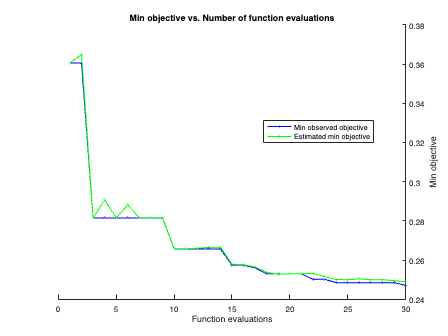

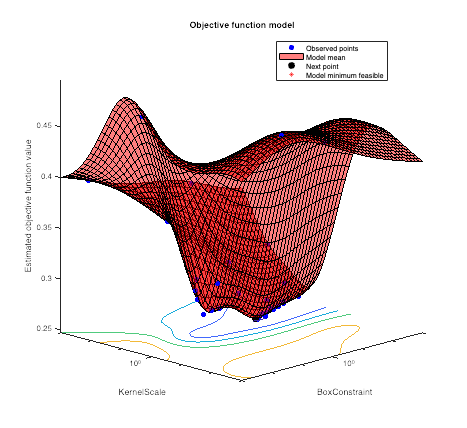


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 172.2264 seconds
Total objective function evaluation time: 128.8413

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

        11.76          3.6785   

Observed objective function value = 0.24708
Estimated objective function value = 0.24858
Function evaluation time = 3.0903

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       15.683           4.211   

Estimated objective function value = 0.24884
Estimated function evaluation time = 3.0918



gtccRBFSvmTURMERxLUSMEG7 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1722×1 double]
                                 Bias: 0.0150
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,18,'test',150) * principalComponentCoeffs;
[lCA, rbfCA] = testModels(testMatrix1,-1,gtccLinearSvmTURMERxLUSMEG7,gtccRBFSvmTURMERxLUSMEG7);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 51.33%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 76.00%


### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,18,'test',150) * principalComponentCoeffs;
[lCA, rbfCA] = testModels(testMatrix2,1,gtccLinearSvmTURMERxLUSMEG7,gtccRBFSvmTURMERxLUSMEG7);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 96.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 48.00%


### With 99% variance captured with PCA

[XTrain99,coeffs99] = projectPCA(XTrain,99);

gtccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.32096 |      3.5957 |     0.32096 |     0.32096 |       62.483 |       69.437 |
|    2 | Accept |      0.4732 |      1.5551 |     0.32096 |     0.33024 |    0.0034575 |       55.606 |
|    3 | Accept |      0.4732 |      1.3846 |     0.32096 |     0.32098 |    0.0014001 |     0.082319 |
|    4 | Accept |     0.46151 |      34.736 |     0.32096 |     0.32098 |        114.3 |     0.015209 |
|    5 | Accept |     0.35052 |      2.5858 |     0.32096 |     0.32099 |       56.306 |        297.7 |
|    6 | Best   |     0.31546 |      3.8322 |     0.31546 |     

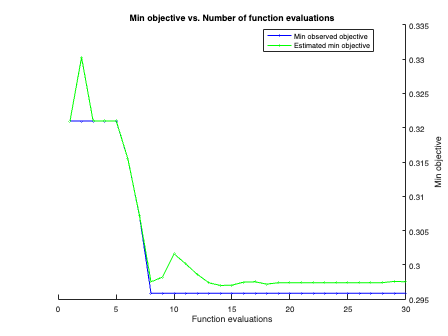

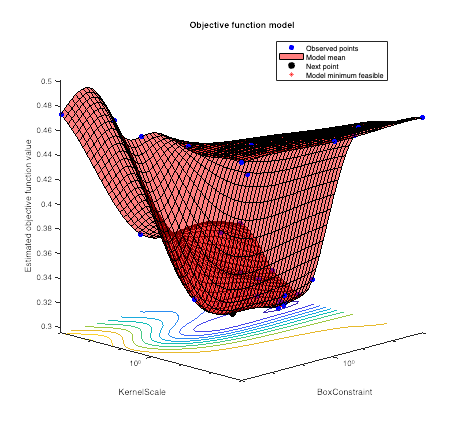


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 409.5779 seconds
Total objective function evaluation time: 378.2143

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

        127.5          7.9567   

Observed objective function value = 0.29588
Estimated objective function value = 0.29773
Function evaluation time = 6.8512

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       168.25          9.7313   

Estimated objective function value = 0.29754
Estimated function evaluation time = 7.4691



gtccRBFSvmTURMERxLUSMEG99 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1753×1 double]
                                 Bias: 2.3501
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,gtccLength,'test',150) * coeffs99;
[lCA, rbfCA] = testModels(testMatrix1,-1,gtccLinearSvmTURMERxLUSMEG99,gtccRBFSvmTURMERxLUSMEG99);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 49.33%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 22.67%


### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,gtccLength,'test',150) * coeffs99;
[lCA, rbfCA] = testModels(testMatrix2,1,gtccLinearSvmTURMERxLUSMEG99,gtccRBFSvmTURMERxLUSMEG99);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 98.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 99.33%


# ----- Helper Functions -----

function [lCA, rbfCA] = testModels(testMatrix,class,linearSVM,rbfSVM)
numTestSamples = size(testMatrix,1);
labelsLinear = predict(linearSVM,testMatrix);
lCA = sum(labelsLinear==class)/numTestSamples;
labelsRbf = predict(rbfSVM,testMatrix);
rbfCA = sum(labelsRbf==class)/numTestSamples;
end

function featureMatrix = buildFeatureMatrix(birdID,gtccLength,type,sampleLimit)
arguments
birdID
gtccLength = 18
type = 'train'
sampleLimit = false
end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if sampleLimit
    limit = sampleLimit;
else
    limit = numel(fileList);
end
featureMatrix = zeros(limit,gtccLength*14*3);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [syllable, fs] = audioread(filePath);
    featureMatrix(ii,:) = extractGtcc(syllable,fs,gtccLength);
end
end